LTI-системы

% dx = Ax + Bu   x, u - от t зависят
% y = Cx + Du 
A = [2 3 -2;
    2 5 1;
    1 -3 2];
B = [1 -1;
    2 1;
    -4 1];
C = [1 1 0;
    0 0 1];
D = zeros(2);

ts = 0.1;

ss_sys = ss(A,B,C,D)

ss_sys =
 
  A = 
       x1  x2  x3
   x1   2   3  -2
   x2   2   5   1
   x3   1  -3   2
 
  B = 
       u1  u2
   x1   1  -1
   x2   2   1
   x3  -4   1
 
  C = 
       x1  x2  x3
   y1   1   1   0
   y2   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Continuous-time state-space model.



tf_sys = tf(ss_sys)

tf_sys =
 
  From input 1 to output...
           3 s^2 - 3 s - 6
   1:  -----------------------
       s^3 - 9 s^2 + 23 s - 39
 
          -4 s^2 + 23 s - 9
   2:  -----------------------
       s^3 - 9 s^2 + 23 s - 39
 
  From input 2 to output...
               3 s + 3
   1:  -----------------------
       s^3 - 9 s^2 + 23 s - 39
 
           s^2 - 11 s + 24
   2:  -----------------------
       s^3 - 9 s^2 + 23 s - 39
 
Continuous-time transfer function.



tf_sys_siso = tf([3, -3, -6], [1,-9,23,-39])

tf_sys_siso =
 
      3 s^2 - 3 s - 6
  -----------------------
  s^3 - 9 s^2 + 23 s - 39
 
Continuous-time transfer function.



frd_sys = frd(ss_sys, 0:10)

frd_sys =

  From input 1 to:

    Frequency(rad/s)         output 1          output 2    
    ----------------         --------          --------    
            0            0.1538 + 0.0000i  0.2308 + 0.0000i
            1            0.1474 + 0.2081i  0.4740 - 0.4191i
            2           -0.1198 + 0.4831i  1.1886 - 0.2780i
            3           -0.5000 + 0.2857i  1.1429 + 0.5000i
            4           -0.5086 + 0.0213i  0.7072 + 0.6876i
            5           -0.4299 - 0.1038i  0.4547 + 0.6427i
            6           -0.3560 - 0.1606i  0.3174 + 0.5711i
            7           -0.2962 - 0.1864i  0.2356 + 0.5071i
            8           -0.2487 - 0.1966i  0.1826 + 0.4542i
            9           -0.2107 - 0.1985i  0.1460 + 0.4105i
           10           -0.1802 - 0.1960i  0.1196 + 0.3741i

  From input 2 to:

    Frequency(rad/s)         output 1           output 2    
    ----------------         --------           --------    
            0           -0.0769 + 0.0000i  -0.


dss_sys_clean = ss(A,B,C,D,ts)

dss_sys_clean =
 
  A = 
       x1  x2  x3
   x1   2   3  -2
   x2   2   5   1
   x3   1  -3   2
 
  B = 
       u1  u2
   x1   1  -1
   x2   2   1
   x3  -4   1
 
  C = 
       x1  x2  x3
   y1   1   1   0
   y2   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.



dss_sys_converted = c2d(ss_sys, ts)

dss_sys_converted =
 
  A = 
            x1       x2       x3
   x1    1.253    0.469  -0.2246
   x2   0.2924    1.675   0.1157
   x3  0.08183  -0.4081    1.192
 
  B = 
            u1       u2
   x1   0.1956  -0.1022
   x2   0.2519   0.1231
   x3  -0.4715  0.08686
 
  C = 
       x1  x2  x3
   y1   1   1   0
   y2   0   0   1
 
  D = 
       u1  u2
   y1   0   0
   y2   0   0
 
Sample time: 0.1 seconds
Discrete-time state-space model.




ss_simple = ss(-1,1,1,0)

ss_simple =
 
  A = 
       x1
   x1  -1
 
  B = 
       u1
   x1   1
 
  C = 
       x1
   y1   1
 
  D = 
       u1
   y1   0
 
Continuous-time state-space model.



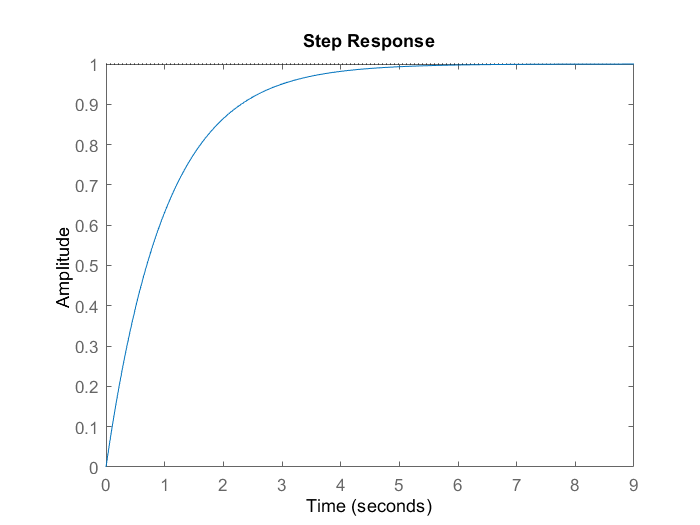

step(ss_simple)


[y, t] = impulse(ss_simple, linspace(0,2,20))

y =     1.0000
    0.9001
    0.8102
    0.7292
    0.6564
    0.5908
    0.5318
    0.4786
    0.4308
    0.3878


t =          0
    0.1053
    0.2105
    0.3158
    0.4211
    0.5263
    0.6316
    0.7368
    0.8421
    0.9474


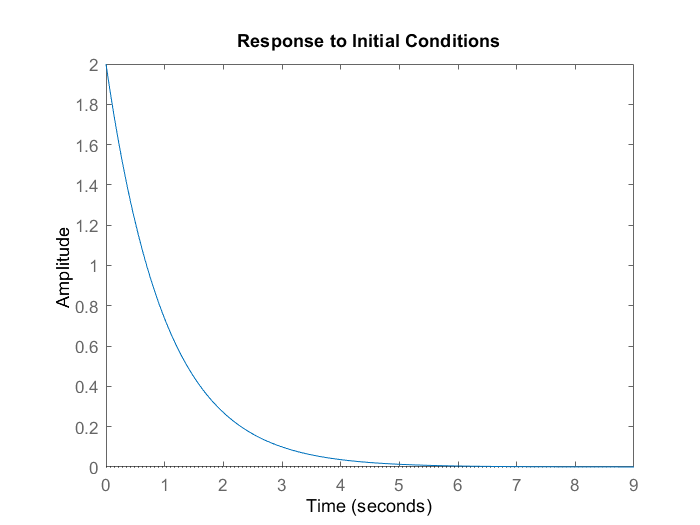


initial(ss_simple, 2)

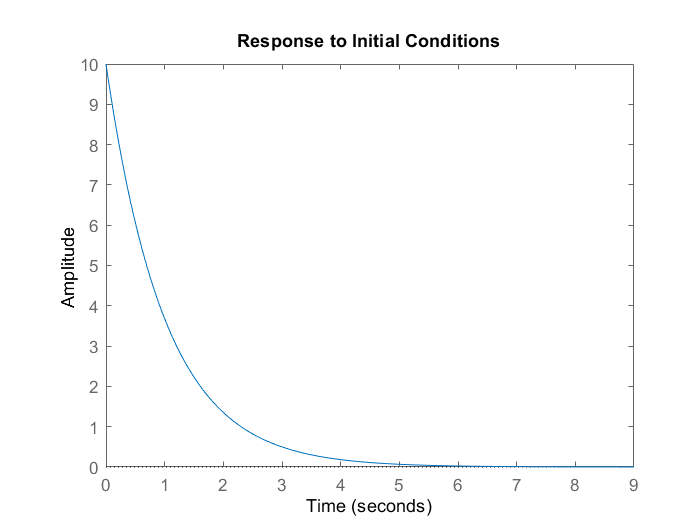

initial(ss_simple, 10)

t = linspace(0,2,200)

t =          0    0.0101    0.0201    0.0302    0.0402    0.0503    0.0603    0.0704    0.0804    0.0905    0.1005    0.1106    0.1206    0.1307    0.1407    0.1508    0.1608    0.1709    0.1809    0.1910    0.2010    0.2111    0.2211    0.2312    0.2412    0.2513    0.2613    0.2714    0.2814    0.2915    0.3015    0.3116    0.3216    0.3317    0.3417    0.3518    0.3618    0.3719    0.3819    0.3920    0.4020    0.4121    0.4221    0.4322    0.4422    0.4523    0.4623    0.4724    0.4824    0.4925


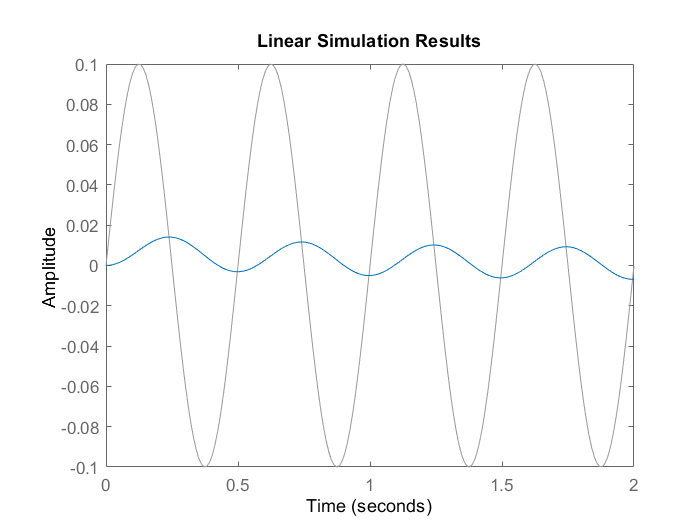

u = 0.1*sin(2*pi*t*2);
lsim(ss_simple, u, t)

zpk_simple = zpk(ss_simple)

zpk_simple =
 
    1
  -----
  (s+1)
 
Continuous-time zero/pole/gain model.

